# Examen Localización de un robot diferencial

Ana Itzel Hernández García 

Limpieza de pantalla

clear all
close all
clc

**Pregunta 2**

Un robot diferencial con los siguientes parámetros:

Radio de las ruedas: 0.1m.

Distancia entre ruedas (eje): L= 0.4m

Pose inicial (x0, y0, θ0) = (0, 0, 0º)

xi(1) = 0;
yi(1) = 0; 
thi(1) = 0;
r = 0.1;
l = 0.4;
N = 20; 
delta_t =1;

w_R = [4.582, 4.773, 5.291, 5.960, 6.490, -1.168, -1.364, 5.960, 5.291, 4.773, 4.582, 4.773, 5.291, 5.960, 6.490, 6.686, 6.490, 5.960, 5.291, 4.773, 4.582];
w_L = [1.701, 2.353, 3.676, 4.856, 5.618, 13.735, 13.472, 4.856, 3.676, 2.353, 1.701, 2.353, 3.676, 4.856, 5.618, 5.881, 5.618, 4.856, 3.676, 2.353, 1.701];

for i = 1:N
    v(i) = r*((w_R(i)+w_L(i))/2);
    w(i) = r*((w_R(i)-w_L(i))/l);

    if w(i) == 0
        xi(i+1) = xi(i) + v(i)* cos(thi(i))* delta_t;
        yi(i+1) = yi(i) + v(i)* sin(thi(i))* delta_t;
        thi(i+1) = thi(i);
        sprintf("Paso: %d", i)
        sprintf("Velocidad lineal: %0.1f | Velocidad angular: %0.1f", v(i), w(i))
        sprintf("pose : x = %0.1f y = %0.1f θ = %0.1f", xi(i+1), yi(i+1),rad2deg(thi(i+1)))
    else 
        xi(i+1) = xi(i) - (v(i)/w(i) * sin(thi(i))) + (v(i)/w(i) * sin(thi(i) + w(i)*delta_t));
        yi(i+1) = yi(i) + (v(i)/w(i) * cos(thi(i))) - (v(i)/w(i) * cos(thi(i) + w(i)*delta_t));
        thi(i+1) = thi(i) + w(i)*delta_t;
        sprintf("Paso: %d", i)
        sprintf("Velocidad lineal: %0.1f | Velocidad angular: %0.1f", v(i), w(i))
        sprintf("pose : x = %0.1f y = %0.1f θ = %0.1f", xi(i+1), yi(i+1),rad2deg(thi(i+1)))
    end
end

ans = "Paso: 1"

ans = "Velocidad lineal: 0.3 | Velocidad angular: 0.7"

ans = "pose : x = 0.3 y = 0.1 θ = 41.3"

ans = "Paso: 2"

ans = "Velocidad lineal: 0.4 | Velocidad angular: 0.6"

ans = "pose : x = 0.5 y = 0.4 θ = 75.9"

ans = "Paso: 3"

ans = "Velocidad lineal: 0.4 | Velocidad angular: 0.4"

ans = "pose : x = 0.5 y = 0.9 θ = 99.1"

ans = "Paso: 4"

ans = "Velocidad lineal: 0.5 | Velocidad angular: 0.3"

ans = "pose : x = 0.3 y = 1.4 θ = 114.9"

ans = "Paso: 5"

ans = "Velocidad lineal: 0.6 | Velocidad angular: 0.2"

ans = "pose : x = 0.0 y = 1.9 θ = 127.4"

ans = "Paso: 6"

ans = "Velocidad lineal: 0.6 | Velocidad angular: -3.7"

ans = "pose : x = 0.3 y = 2.0 θ = -86.1"

ans = "Paso: 7"

ans = "Velocidad lineal: 0.6 | Velocidad angular: -3.7"

ans = "pose : x = 0.0 y = 2.1 θ = -298.6"

ans = "Paso: 8"

ans = "Velocidad lineal: 0.5 | Velocidad angular: 0.3"

ans = "pose : x = 0.2 y = 2.6 θ = -282.8"

ans = "Paso: 9"

ans = "Velocidad lineal: 0.4 | Velocidad angular: 0.4"

ans = "pose : x = 0.2 y = 3.0 θ = -259.7"

ans = "Paso: 10"

ans = "Velocidad lineal: 0.4 | Velocidad angular: 0.6"

ans = "pose : x = 0.1 y = 3.3 θ = -225.0"

ans = "Paso: 11"

ans = "Velocidad lineal: 0.3 | Velocidad angular: 0.7"

ans = "pose : x = -0.2 y = 3.5 θ = -183.7"

ans = "Paso: 12"

ans = "Velocidad lineal: 0.4 | Velocidad angular: 0.6"

ans = "pose : x = -0.6 y = 3.4 θ = -149.1"

ans = "Paso: 13"

ans = "Velocidad lineal: 0.4 | Velocidad angular: 0.4"

ans = "pose : x = -0.9 y = 3.1 θ = -125.9"

ans = "Paso: 14"

ans = "Velocidad lineal: 0.5 | Velocidad angular: 0.3"

ans = "pose : x = -1.1 y = 2.6 θ = -110.1"

ans = "Paso: 15"

ans = "Velocidad lineal: 0.6 | Velocidad angular: 0.2"

ans = "pose : x = -1.3 y = 2.0 θ = -97.6"

ans = "Paso: 16"

ans = "Velocidad lineal: 0.6 | Velocidad angular: 0.2"

ans = "pose : x = -1.3 y = 1.4 θ = -86.1"

ans = "Paso: 17"

ans = "Velocidad lineal: 0.6 | Velocidad angular: 0.2"

ans = "pose : x = -1.2 y = 0.8 θ = -73.6"

ans = "Paso: 18"

ans = "Velocidad lineal: 0.5 | Velocidad angular: 0.3"

ans = "pose : x = -1.0 y = 0.3 θ = -57.8"

ans = "Paso: 19"

ans = "Velocidad lineal: 0.4 | Velocidad angular: 0.4"

ans = "pose : x = -0.7 y = -0.0 θ = -34.7"

ans = "Paso: 20"

ans = "Velocidad lineal: 0.4 | Velocidad angular: 0.6"

ans = "pose : x = -0.3 y = -0.1 θ = -0.0"

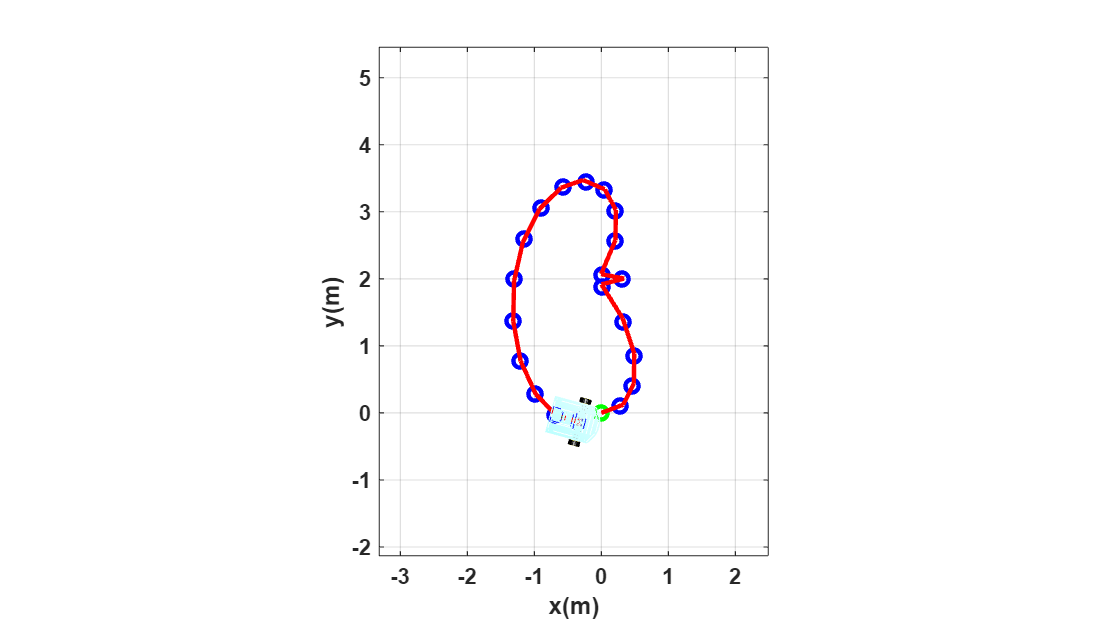


%%%%%% Contron Lazo Abierto %%%%%%%%%%%%%

% Parámetros del movimiento
ts = 0.01;       % Tiempo de muestreo
v = 5;         % Velocidad lineal
w = 10;         % Velocidad angular

% Inicialización del robot
x = xi(1); y = yi(1); theta = 0; % Posición y orientación inicial
x1 = []; y1 = []; phi = []; % Trayectoria simulada
hx = []; hy = [];          % Historia del centro del robot

for i = 1:(length(xi)-1)
    x_goal = xi(i+1);
    y_goal = yi(i+1);
    
    % ROTACIÓN EN EL LUGAR
    % Calcular el ángulo al objetivo
    angle_to_goal = atan2(y_goal - y, x_goal - x);
    
    % Calcular la diferencia de ángulos más corta
    angle_diff = angle_to_goal - theta;
    
    % Normalizar la diferencia de ángulos para estar en el rango [-pi, pi]
    angle_diff = mod(angle_diff + pi, 2*pi) - pi;
    
    % Calcular el tiempo necesario para rotar
    t_rot = abs(angle_diff) / w;  % Tiempo en segundos para llegar al ángulo
    
    % Actualizar la orientación del robot
    theta = theta + angle_diff;
    
    % Registrar la trayectoria
    x1(end+1) = x;
    y1(end+1) = y;
    phi(end+1) = theta;
    hx(end+1) = x;
    hy(end+1) = y;

    % Calcular la distancia al objetivo
    dist = sqrt((x_goal - x)^2 + (y_goal - y)^2);
    
    % Calcular el tiempo necesario para moverse hasta el objetivo
    t_trans = dist / v;  % Tiempo en segundos para cubrir la distancia
    
   % Movimiento lineal paso a paso
    n_steps = ceil(t_trans / ts); % Número de pasos
    for j = 1:n_steps
        x = x + v * cos(theta) * ts;
        y = y + v * sin(theta) * ts;
    
        % Registrar trayectoria paso a paso
        x1(end+1) = x;
        y1(end+1) = y;
        phi(end+1) = theta;
        hx(end+1) = x;
        hy(end+1) = y;
    end
end

% Tiempo total de simulación
k_global = length(x1);


%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACIÓN VIRTUAL %%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Configuración de escena
scene = figure;
set(scene,'Color','white');
set(gca,'FontWeight','bold');
sizeScreen = get(0,'ScreenSize');
set(scene,'position',sizeScreen);
camlight('headlight');
axis equal;
grid on;
box on;
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)');
view([0 90]);

% Límites automáticos
xmin_lim = min(xi) - 2;
xmax_lim = max(xi) + 2;
ymin_lim = min(yi) - 2;
ymax_lim = max(yi) + 2;
axis([xmin_lim xmax_lim ymin_lim ymax_lim 0 1]);
% Gráfica inicial
scale = 4;
MobileRobot_5; 
H1 = MobilePlot_4(x1(1), y1(1), phi(1), scale); hold on;
H2 = plot3(hx(1), hy(1), 0, 'r', 'lineWidth', 2);
H3 = plot3(xi, yi, 0 * ones(size(xi)), 'bo', 'lineWidth', 2);
H4 = plot3(hx(1), hy(1), 0, 'go', 'lineWidth', 2);

% Animación
step = 1;
for k = 1:step:k_global
    delete(H1);
    delete(H2);
    H1 = MobilePlot_4(x1(k), y1(k), phi(k), scale);
    H2 = plot3(hx(1:k), hy(1:k), zeros(1,k), 'r', 'lineWidth', 2);
    pause(ts);
end